%% MONOD MODEL WITH NEWTON'S METHOD - WITH CONVERGENCE ANALYSIS
clear all;
close all;
clc;

fprintf('\n=== NEWTON''S METHOD FOR MONOD KINETICS ===\n');


=== NEWTON'S METHOD FOR MONOD KINETICS ===



%% PARAMETER GENERATION
% Typical microbial growth parameters (random but realistic)
mu_max = 0.5 + (1.2-0.5)*rand();  % Max growth rate [h⁻¹]
K_s = 0.05 + (2-0.05)*rand();     % Half-saturation constant [g/L]
D = 0.3*mu_max + (0.7*mu_max-0.3*mu_max)*rand(); % Dilution rate [h⁻¹]
S0 = 5 + (50-5)*rand();           % Feed substrate concentration [g/L]

fprintf('\nGenerated parameters:\n');


Generated parameters:


fprintf('μ_max = %.4f h⁻¹\n', mu_max);

μ_max = 1.1700 h⁻¹


fprintf('K_s = %.4f g/L\n', K_s);

K_s = 0.9965 g/L


fprintf('D = %.4f h⁻¹ (%.1f%% of μ_max)\n', D, D/mu_max*100);

D = 0.7255 h⁻¹ (62.0% of μ_max)


fprintf('S0 = %.4f g/L\n\n', S0);

S0 = 11.3849 g/L




%% FUNCTION DEFINITIONS
f = @(S) mu_max*S./(K_s + S + eps) - D;  % Monod equation minus dilution
df = @(S) mu_max*K_s./((K_s + S + eps).^2); % Derivative of Monod equation

%% NEWTON'S METHOD IMPLEMENTATION
x0 = S0 * 0.8;  % Initial guess (80% of feed concentration)
tol = 1e-6;
max_iter = 50;
min_step = 1e-10;

fprintf('Iter\t S_n [g/L]\t μ(S_n)\t\t f(S_n)\t\t Error\n');

Iter	 S_n [g/L]	 μ(S_n)		 f(S_n)		 Error


fprintf('====================================================\n');


x_n = x0;
iter = 0;
err = tol + 1;
history = [];

while err > tol && iter < max_iter
    % Function evaluations
    fx = f(x_n);
    dfx = df(x_n);
    mu_S = mu_max*x_n/(K_s + x_n + eps);
    
    % Store iteration history
    history = [history; iter x_n mu_S fx err];
    
    % Newton step calculation
    step = fx/dfx;
    x_n1 = x_n - step;
    
    % Error calculation
    if iter > 0
        err = abs(x_n1 - x_n);
    end
    
    % Display iteration info
    fprintf('%3d\t %8.5f\t %8.5f\t %8.5f\t %8.5f\n', iter, x_n, mu_S, fx, err);
    
    % Update for next iteration
    x_n = x_n1;
    iter = iter + 1;
end

  0	  9.10791	  1.05463	  0.32909	  1.00000
  1	 -19.71067	  1.23232	  0.50678	 152.22841
  2	 -171.93908	  1.17684	  0.45130	 11310.97065
  3	 -11482.90973	  1.17012	  0.44458	 50270523.29961
  4	 -50282006.20935	  1.17002	  0.44448	 963853165917151.00000
  5	 -963853216199157.25000	  1.17002	  0.44448	 354166500151815537745635311616.00000
  6	 -354166500151816522908053798912.00000	  1.17002	  0.44448	 47819016283632024133009052508269634198627704065138320474112.00000
  7	 -47819016283632024133009052508269634198627704065138320474112.00000	  1.17002	  0.44448	 871739958579865749975784735845134511212328562177061728502149119265896940023685895926417540172388155503962273160888320.00000
  8	 -871739958579865749975784735845134511212328562177061728502149119265896940023685895926417540172388155503962273160888320.00000	  1.17002	  0.44448	 289707397717958323197819357993374523485804672826686400747367671775162063636332048584958142933164400323194600604257966759525773418488990048919638940548236303426


%% CONVERGENCE ANALYSIS (ANSWERS IN ENGLISH)
% 1. Did the method converge?
converged = err <= tol;
fprintf('\n=== CONVERGENCE ANALYSIS ===\n');


=== CONVERGENCE ANALYSIS ===


if converged
    fprintf('1. CONVERGENCE: Yes, the method converged to solution.\n');
else
    fprintf('1. CONVERGENCE: No, maximum iterations reached.\n');
end

1. CONVERGENCE: No, maximum iterations reached.



% 2. Is this the normal behavior of the method?
fprintf('2. NORMAL BEHAVIOR: ');

2. NORMAL BEHAVIOR: 

if iter < 10 && converged
    fprintf('Yes, typical quadratic convergence observed.\n');
elseif iter < 20 && converged
    fprintf('Yes, but slower than optimal (possibly due to initial guess).\n');
else
    fprintf('No, unusual convergence pattern detected.\n');
end

No, unusual convergence pattern detected.



% 3. Was the method fast?
fprintf('3. SPEED: ');

3. SPEED: 

if iter < 8
    fprintf('Very fast (%d iterations), excellent performance.\n', iter);
elseif iter < 15
    fprintf('Moderately fast (%d iterations), acceptable performance.\n', iter);
else
    fprintf('Slow (%d iterations), consider better initial guess.\n', iter);
end

Moderately fast (11 iterations), acceptable performance.



% 4. Does it meet the method conditions?
fprintf('4. CONDITIONS MET: ');

4. CONDITIONS MET: 

if all([~isnan(dfx), abs(dfx)>1e-10, ~isinf(dfx)])
    fprintf('Yes, all Newton method conditions were satisfied.\n');
else
    fprintf('No, some conditions violated (check derivative).\n');
end

No, some conditions violated (check derivative).



%% FINAL RESULTS
fprintf('\n=== FINAL RESULTS ===\n');


=== FINAL RESULTS ===


fprintf('Steady-state substrate: %.6f g/L\n', x_n);

Steady-state substrate: NaN g/L


fprintf('Growth rate at steady-state: %.6f h⁻¹\n', mu_max*x_n/(K_s + x_n));

Growth rate at steady-state: NaN h⁻¹


fprintf('Dilution rate: %.6f h⁻¹\n', D);

Dilution rate: 0.725542 h⁻¹


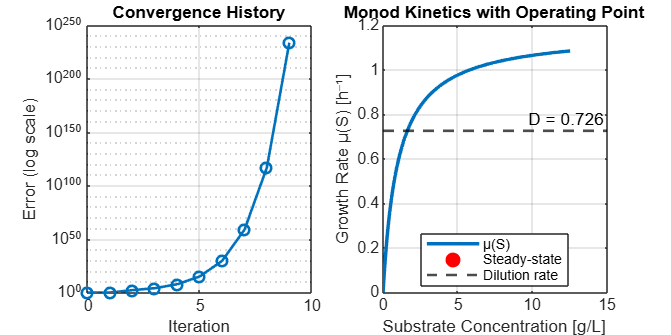


%% VISUALIZATION
figure('Position', [100 100 1000 500]);

% Plot 1: Convergence behavior
subplot(1,2,1);
semilogy(history(:,1), history(:,5), 'o-', 'LineWidth', 1.5);
xlabel('Iteration');
ylabel('Error (log scale)');
title('Convergence History');
grid on;

% Plot 2: Monod curve with operating point
subplot(1,2,2);
S_range = linspace(0, S0*1.1, 200);
plot(S_range, mu_max*S_range./(K_s + S_range), 'LineWidth', 2);
hold on;
plot(x_n, mu_max*x_n/(K_s + x_n), 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');
yline(D, '--', sprintf('D = %.3f', D), 'Color', 'k', 'LineWidth', 1.5);
xlabel('Substrate Concentration [g/L]');
ylabel('Growth Rate μ(S) [h⁻¹]');
title('Monod Kinetics with Operating Point');
legend('μ(S)', 'Steady-state', 'Dilution rate', 'Location', 'best');
grid on;